# Let's get familiar with the **Impulse Response Function** (IRFs) and the inverse **FFT**

Although not a rigorous proof we can show how to compute an** Impulse Response Function (IRF)** from a measured **FRF** by using the **Inverse Fast Fourier transform (ifft)**.  The workflow involves the following steps

- Say we have a conjugate symmetric measured FRF $H_m \left(k\ldotp \Delta \omega \right)$

- The IRF is:    $h\left(k\ldotp \Delta t\right)\;=\;\frac{\mathbf{ifft}\left(\;H_{m\;} \right)}{\Delta t}$     where  [`ifft()`](matlab:  web(fullfile(docroot, 'matlab/ref/ifft.html')))  is MATLAB's Inverse Fast Fourier Transform function

`Bradley Horton: bhorton@mathworks.com`

## Define Analytic system to explore:

Clear your workspace

clear

First let's define **Transfer Function**:

- 
$$H\left(s\right)\;\;=\;\;\frac{1}{s^2 \;\;+\;\;\;2\ldotp \zeta \ldotp \omega_n \ldotp s\;\;\;+\;\;\;\omega_n^2 }$$


This transfer function has POLES at:

- 
$$\lambda \;\;=\;\;-\zeta \ldotp {\omega_n \;\;+\;\;j\ldotp \omega_n \ldotp \sqrt{1-\zeta^2 }}_{\;}$$


- 
$$\bar{\lambda} \;\;=\;\;-\zeta \ldotp {\omega_n \;\;-\;\;j\ldotp \omega_n \ldotp \sqrt{1-\zeta^2 }}_{\;}$$


dr = 0.1;     % (-)
fn = 200;     % (Hz)
wn = 2*pi*fn; % (rad/sec)

THE_POLES = [(-dr*wn + 1i*wn*sqrt(1 - dr^2));
             (-dr*wn - 1i*wn*sqrt(1 - dr^2)) ]

THE_POLES = 1.0e+03 *

  -0.1257 + 1.2503i
  -0.1257 - 1.2503i



H_true    = @(s)  1 ./ (s.^2  +  2*dr*wn*s + wn^2)

H_true = function_handle with value:
    @(s)1./(s.^2+2*dr*wn*s+wn^2)


MAG       = @(x) abs(x);

Now compute the analytical **Impulse Response Function (IRF)**

- 
$$h\left(t\right)\;=\;L^{-1} \left\lbrack H\left(s\right)\right\rbrack$$


s             = sym('s');
H_true_sym    = 1 / (s^2  +  2*dr*wn*s + wn^2);

irf_true_sym  = ilaplace(H_true_sym)

$$irf\_true\_sym = \frac{{\mathrm{e}}^{-40\,\pi \,t}\,\sin\left(t\,\sqrt{\frac{3391170250170917}{2147483648}-1600\,\pi^{2}}\right)}{\sqrt{\frac{3391170250170917}{2147483648}-1600\,\pi^{2}}}$$

irf_true      = matlabFunction(irf_true_sym)

irf_true = function_handle with value:
    @(t)exp(t.*pi.*-4.0e+1).*sin(t.*1.250338089131317e+3).*7.997836814639136e-4


clear s

## Set up sampling:

Fs_hz   = 1000;  % (Hz)
dt      = 1/Fs_hz;
N       = 2^13;  % 8192 == 2^13
df_hz   = 1/(N*dt);

t_col   =    dt*[0:(N-1)].';
fhz_col = df_hz*[0:(N-1)].';

## FRF, true:  Sample it and create conjugate symmetric

Recall that the **Frequency Response Function** (FRF) is just the Transfer function evaluated along the imaginary axis, i.e.:

- 
$$\mathrm{FRF}\left(\omega \right)\;\;=\;\;H\left(s=j\ldotp \omega \right)$$


H_FRF_true_samp_FULL = H_true(j*2*pi*fhz_col);

Create a complex conjugate reflection about the Nyquist frequency.  For sample lengths `"N"` that are even, the reflection point is at the following position in the list:

-  
$$\frac{N}{2}+1$$


% y = [1:8].';
% Y=fft(y);
% [y  Y]
% 
%    1.0000            36.0000          
%    2.0000            -4.0000 + 9.6569i
%    3.0000            -4.0000 + 4.0000i
%    4.0000            -4.0000 + 1.6569i
%    5.0000            -4.0000          
%    6.0000            -4.0000 - 1.6569i
%    7.0000            -4.0000 - 4.0000i
%    8.0000            -4.0000 - 9.6569i

THE_MID =   abs(H_FRF_true_samp_FULL(N/2 + 1)) * ...
           sign(H_FRF_true_samp_FULL(N/2 + 1)) ;

the_front = H_FRF_true_samp_FULL( 1:(N/2) ); 

the_back  =   conj(  the_front(2:end)   );
the_back  = flipud(the_back);
       

So our "true" FRF, mirrored about it's Nyquist frequency is:

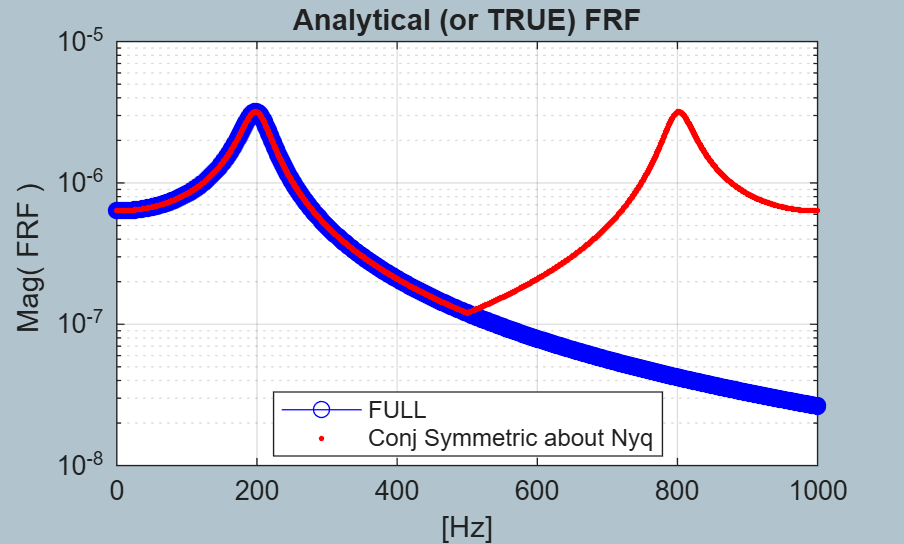

H_FRF_true_samp_MIRR = [ the_front;
                         THE_MID;
                         the_back;  ];

figure('Name', 'True:  FRF');
    semilogy(fhz_col, MAG(H_FRF_true_samp_FULL), '-bo', ...
             fhz_col, MAG(H_FRF_true_samp_MIRR), '.r');
        grid on, xlabel('[Hz]'), ylabel('Mag( FRF ) ');
        legend({'FULL','Conj Symmetric about Nyq'}, "Location","best");
        title('Analytical (or TRUE) FRF');

## IRF, true:    Sample it

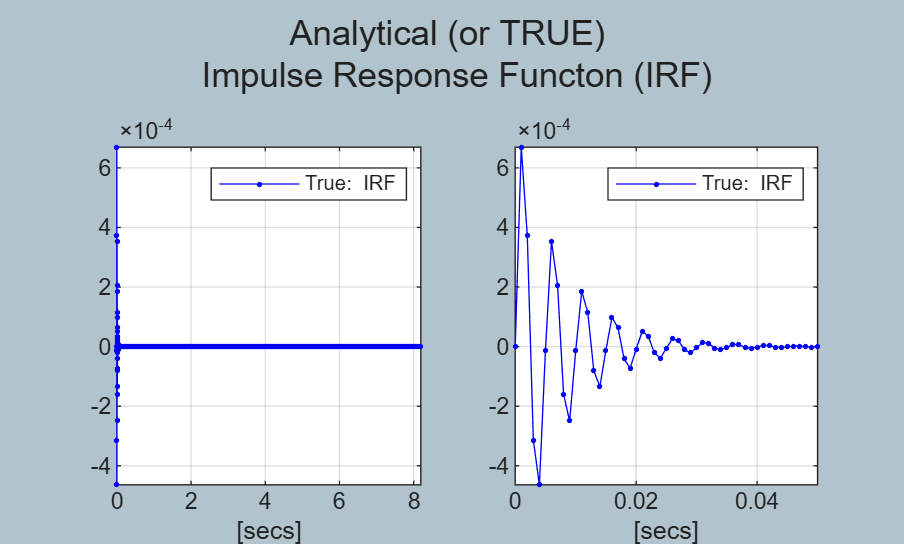

irf_true_samp = irf_true(t_col);

figure('Name', 'True: IRF')
    subplot(1,2,1)
       plot(t_col, irf_true_samp, '-b.');
           grid on, xlabel('[secs]'), axis tight
       legend('True:  IRF')
    subplot(1,2,2);  
       IND = find(t_col <= 0.05);
       plot(t_col(IND), irf_true_samp(IND), '-b.');
           grid on, xlabel('[secs]'), axis tight
       legend('True:  IRF')
    tmp_str = sprintf('Analytical (or TRUE) \n Impulse Response Functon (IRF)');
    sgtitle(tmp_str);

## IRF, calc:   Use the ifft to compute the IRF

Recall the **Inverse Fourier transform** written using **HERTZ** units, ie:   $\omega =2\ldotp \pi \ldotp f$  

-   
$$h\left(t\right)=\int_{-\infty }^{\infty } H\left(j\ldotp 2\ldotp \pi \ldotp f\right)\ldotp e^{\mathrm{j2}\pi \mathrm{ft}\;} \ldotp \mathrm{df}\;$$


If we discretize time via:

- $\mathrm{dt}=\Delta \;$     and   $t_m \;=m\ldotp \Delta \;\;$   

And if we discretize frequency via:   

- $\mathrm{df}=\frac{1}{N\ldotp \Delta \;}\;$     and    $f_k \;=\;k\ldotp \mathrm{df}\;=\;\frac{k}{N\ldotp \Delta \;}$

Then our sampled IRF can be written as:

- 
$$h\left(m\ldotp \Delta \right)=\;$$

$$\left(\sum_{k=0}^{N-1} H_k \;\ldotp e^{j\ldotp 2\ldotp \pi \ldotp k\ldotp \frac{m\ldotp \Delta \;}{N\ldotp \Delta }} \right)\ldotp \frac{1}{N\ldotp \Delta \;}$$


- 
$$h\left(m\ldotp \Delta \right)=\frac{1}{\Delta \;}\;\ldotp \;\left(\frac{1}{N}\;\ldotp \sum_{k=0}^{N-1} H_k \;\ldotp e^{\frac{j\ldotp 2\ldotp \pi \ldotp k\ldotp m}{N}} \right)$$
 

- $h\left(m\ldotp \Delta \right)=\frac{1}{\Delta \;}$.` ifft(H)   `where     [`ifft()`](matlab:  web(fullfile(docroot, 'matlab/ref/ifft.html')))  is MATLAB's Inverse Fast Fourier Transform function

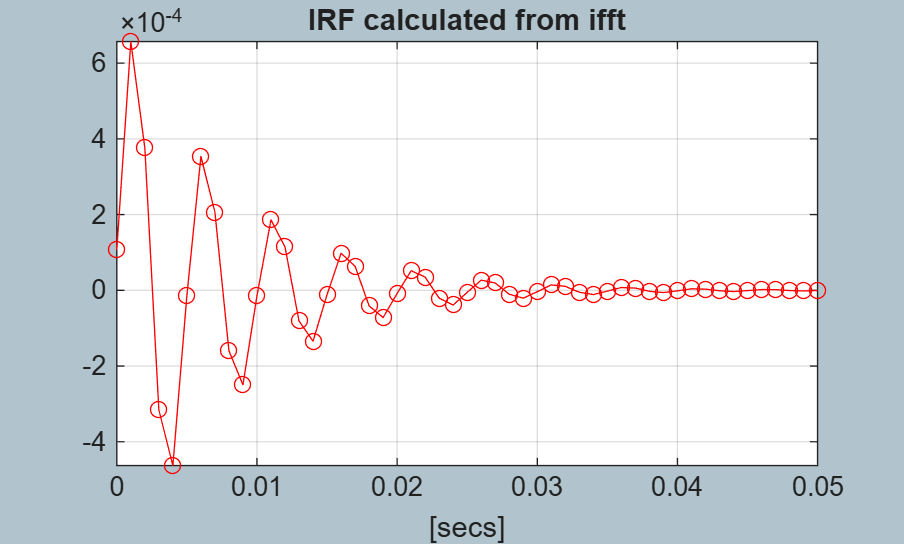

irf_est_B = ifft(H_FRF_true_samp_MIRR)/dt;
irf_est_B = real(irf_est_B); % small imag may occur as numerical noise

IND       = find(t_col <= 0.05);

figure('Name', 'Calculated IRF')
   plot(t_col(IND), irf_est_B(IND), '-ro');
        grid on, xlabel('[secs]'), axis tight
        title( 'IRF calculated from ifft')

## IRF, compare:  Compare the calculated IRF against the True IRF

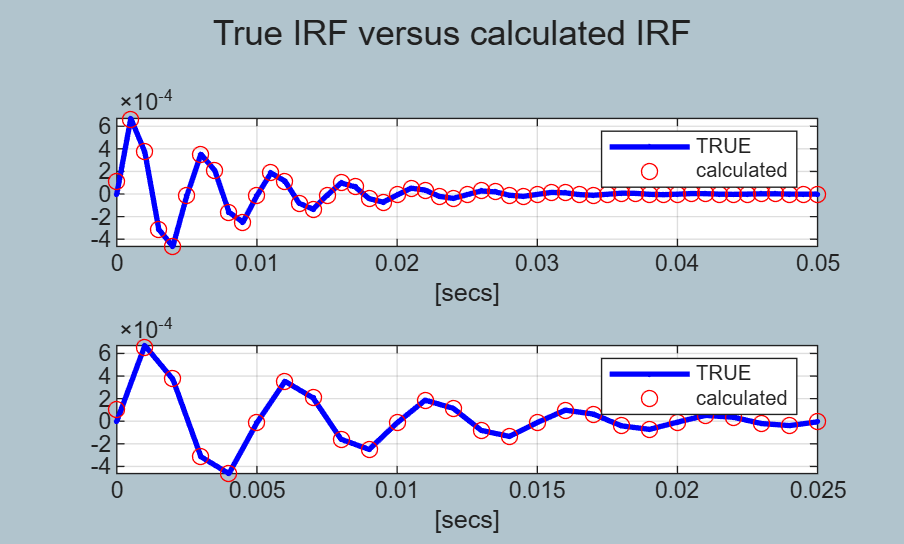

figure('Name','Compare: IRF');
    subplot(2,1,1);  
       IND = find(t_col <= 0.05);
       plot(t_col(IND), irf_true_samp(IND), '-b.', 'LineWidth', 2);
    hold on
       plot(t_col(IND), irf_est_B(IND), 'or');
           grid on, xlabel('[secs]'), axis tight
       legend('TRUE','calculated')

    subplot(2,1,2);  
       IND = find(t_col <= 0.025);
       plot(t_col(IND), irf_true_samp(IND), '-b.', 'LineWidth', 2);
    hold on
       plot(t_col(IND), irf_est_B(IND), 'or');
           grid on, xlabel('[secs]'), axis tight
       legend('TRUE','calculated')

    sgtitle("True IRF versus calculated IRF");       